# **Matlab 绘图**

# **1. 二维图形的绘制**

       本质就是将平面坐标上的数据点连接起来的平面图形，可采用直角坐标系。对数坐标系。极坐标系等等，数据点一般以向量或者矩阵的形式给出的，类型可以是实数也可以是复数，二维图像绘制是绘图操作的基础。

**1.1 连线图 - plot**

· plot(x)：x为向量时，以该元素的下标为横坐标 元素值为纵坐标绘出曲线

· plot(x,y)：以x为横坐标，y为纵坐标画图

· plot(x1,y1,x2,y2)： 绘制以x1为横坐标、y1为纵坐标的曲线1， 以x2为横坐标、y2为纵坐标的曲线2，等等。 其中x为横坐标，y为纵坐标，绘制y=f(x)函数曲线。

· plotyy(x1,y1,x2,y2)：绘制双纵坐标图

· plot3(x,y,z)：绘制三维连线图

% plot()函数

% ex1 绘制普通的二维函数图形  
x = 0:pi/100:2*pi;
y = 2*exp(-0.5*x).*sin(2*pi*x);
plot(x,y)
% tips：绘图两步走：1.确定x轴间隔点 2.确定每个间隔点的函数值
% 注意：什么时候用乘，什么时候用点乘

% ex2 绘制参数方程给出的二维曲线
t = -pi:pi/100:pi;
x = t.*cos(3*t);
y = t.*sin(t).*sin(t);
plot(x,y)
% 以上的x与y都是长度相同的向量

% ex3 同时绘制4幅图像 sin(x)、cos(x)以及e^x
x = -3*pi:pi/100:3*pi
y = [1000*sin(x);1000*cos(x);exp(x);1000*cos(x+1)]
plot(x,y)
% 注意：当x是向量，而y是矩阵的时候，x的长度与矩阵y的行数或列数必须相等，如果x的长度等于y的列数，则以x和y的每行为横、纵坐标
% 绘制图像，反之亦然。 ex3中我们举得例子便是x的长度等于y的列数，所以绘制图像的个数便是y的行数，即三个。

% ex4 x与y为同型矩阵时，则以x、y对应列元素为横、纵坐标分别绘制图像
t1 = -3*pi:pi/100:3*pi;
t2 = -pi:pi/300:pi;
x = [t1;t2;].';
y = [10*sin(t1);exp(t2)].';
plot(x,y)
% 注意：x和y此时为同型矩阵，且是列对应，注意转置的运用

% ex5 绘制折线图
x = [1,2,3,4,5,6,7,5,3,-3];
plot(x)

% ex6 绘制复平面的图像
x = 0:pi/100:2*pi;
y = exp(1i*x);
plot(y)

% ex7 plot含多个参数的情况
x1 = -3:1/100:3;
x2 = -pi:pi/100:pi;
x3 = -4:1/100:4;
y1 = 5*cos(x1);
y2 = 5*sin(x2);
y3 = 5*sin(x3).*cos(x3);
plot(x1,y1,x2,y2,x3,y3)

% ex8 plot中的各种选项
% 1.线形选项
% -实线 -.点画线 :虚线 --双画线

% 2.颜色选项
% b 蓝色 m 品红色
% g 绿色 y 黄色
% r 红色 k 黑色
% c 青色 w 白色

% 3.标记符号选项
% .点
% o小圆圈
% x叉叉
% +加号
% *星号

x = 0:pi/100:2*pi;
y = 2*exp(-0.5*x).*sin(2*pi*x);
plot(x,y,'--m*')

% ex9 绘制包络
x = 0:pi/100:2*pi;
y1 = 2*exp(-0.5*x).*sin(2*pi*x);
y2 = [2*exp(-0.5*x);-2*exp(-0.5*x)]
plot(x,y1,'r',x,y2,'b--')
grid

% ex10 绘制双纵坐标函数plotyy
t1 = -3*pi:pi/100:3*pi;
t2 = -3*pi:pi/300:3*pi;
y1 = 10*sin(t1);
y2 = 3*cos(t2);
plotyy(t1,y1,t2,y2)


**    - 绘制图形的一些辅助操作**

% 辅助操作使图像意义更加明确，可读性更强


% 图形标注（图形名，x、y轴名称，图形说明，图例）
% ex11
x = 0:pi/100:2*pi;
y1 = 2*exp(-0.5*x).*sin(2*pi*x);
y2 = [2*exp(-0.5*x);-2*exp(-0.5*x)]
plot(x,y1,'r',x,y2,'b--')
grid;%加网格
title('信号波形及其包络');
xlabel('时间t_{\bf\alpha}'); %文本编辑支持LaTeX语法  markdown语法
ylabel('信号幅值y_{1}');
text(3.7,0.7,'可见包络随着震荡幅值减小而降低');
legend('信号波形','包络线');

% 图形保持
% ex12
x = 0:pi/100:2*pi;
y1 = 2*exp(-0.5*x).*sin(2*pi*x);
y2 = [2*exp(-0.5*x);-2*exp(-0.5*x)]
plot(x,y1,'r',x,y2,'b--')
hold on; %图形保持，可用来叠加图层
plot(x,cos(x))

% 图形窗口分割（画多个子图）
% ex13
% subplot(m,n,p)  分成m*n个绘图区，即m行n列，选择第p个区为绘图区
x = linspace(0,2*pi,60);
y1 = sin(x);
y2 = cos(x);
y3 = 2*exp(-0.5*x).*sin(2*pi*x);
y4 = sin(x).*cos(x);
%进行画布分割
subplot(2,2,1);
plot(x,y1)
title('sin(x)');
grid;

subplot(2,2,2);
plot(x,y2,'r')
title('cos(x)');
grid;

subplot(2,2,3);
plot(x,y3,'m')
title('2^(-0.5*x)*sin(2*pi*x');
grid;

subplot(2,2,4);
plot(x,y4,'k')
title('sin(x)*cos(x)');
grid;




% 还可以进行更灵活的分割
x = linspace(0,2*pi,200);
y1 = sin(x);
y2 = cos(x);
y3 = 2*exp(-0.5*x).*sin(2*pi*x);
y4 = sin(x).*cos(x);
%进行画布分割
subplot(2,2,1);
plot(x,y1)
title('sin(x)');
grid;

subplot(4,4,3);
plot(x,y2,'r')
title('cos(x)');
grid;

subplot(2,1,2);
plot(x,y3,'m')
title('2^(-0.5*x)*sin(2*pi*x');
grid;

subplot(4,4,4);
plot(x,y4,'k')
title('sin(x)*cos(x)');
grid;


subplot(4,4,7);
plot(x,y4,'k')
title('sin(x)*cos(x)');
grid;


subplot(4,4,8);
plot(x,y4,'k')
title('sin(x)*cos(x)');
grid;


**1.2 自适应采样（非等间隔采样）： fplot**

% 采用自适应采样（非等间隔采样）
% 比如绘制cos(tan(pi*x))

% ex14
%等间隔采样
x = [0:1/1000:1];
y = cos( tan(pi*x));
plot(x,y)
%自适应采样
fplot(@(x)cos(tan(pi*x)),[0,1])

**1.3 极坐标系绘图：polar**

% ex15 绘制极坐标系蝴蝶曲线
t = 0:pi/50:20*pi;
r1 = exp(cos(t))-2*cos(4*t)+sin(t/12).^5;
r2 = exp(cos(t-pi/2))-2*cos(4*(t-pi/2))+sin((t-pi/2)/12).^5;

subplot(1,2,1);
polar(t,r1)
subplot(1,2,2);
polar(t,r2,'r')

**1.4 条形图：bar**

bar(y) 创建一个条形图，y 中的每个元素对应一个条形。如果 y 是 m×n 矩阵，则 bar 创建每组包含 n 个条形的 m 个组，即一个条形里面是各个成分的累计

% 条形图
% ex16
bar([1 2 3 4 2 1])

% ex17
A = magic(4)
bar(A) % 若为矩阵，则分别比较y的每一行元素的大小，横坐标为矩阵的行数

% ex18
% group 与 stack
A = [1 2 3;4 5 6;7 8 9;10 11 12;]
subplot(1,2,1);
bar(A,'grouped')
title('Group');

subplot(1,2,2);
bar(A,'stacked')
title('Stack');


**1.5 直方图：hist直角坐标系 ，rose极坐标系**

% ex19 直角坐标系
y = randn(800,1);
subplot(2,2,1);
hist(y);title('高斯分布直方图');% 默认 x 为常量 10

subplot(2,2,2);
x = 50;
hist(y,x);title('指定常量的高斯分布直方图')

subplot(2,2,3);
x = -4:0.1:4;
hist(y,x);title('指定范围的高斯分布直方图1')

subplot(2,2,4);
x = -4:0.01:4;
hist(y,x);title('指定范围的高斯分布直方图2')


% ex20 极坐标系
y = randn(500,1);
theta = y*pi;
rose(theta)
title('极坐标系下的直方图');




**1.6 饼图：pie(x)**

pie(x, explode): explode 为偏移量

pie(x, {'a','b','c'}): {'a','b','c'} 为文字描述，会代替概率百分比

% 某次考试优秀、良好、中等、及格、不及格的人数分别为7、17、23、19、5，试用饼图表示
pie([7 17 23 19 5],[0 0 0 0 1])
title('大饼图（向量）');
legend('优秀',' 良好','中等','及格','不及格');

pie([7 17 23; 19 5 8],[0 0 0 0 1 1])
title('大饼图（矩阵）');
legend('优秀',' 良好','中等','及格','不及格','差下');
% 注意：x可以为向量或矩阵，为向量时，按照逆时针顺序分别为x的各个元素；
% 若为矩阵，则按照列的顺序依次排列矩阵元素，若x元素和小于一，则饼图是不完整的圆。


**1.7 面积统计图：area(x)**

x = 1:1:9;
y=[5 6 9 6 4 7 6 9 3];
area(x,y);
grid;title('面积统计图示例（向量）');

x = 1:2:9;
y=[1 3 5 2 6; 2 4 5 6 2; 5 4 7 2 2].';
area(x,y);
grid;title('面积统计图示例（矩阵）');
% 若x为向量，y为矩阵，则矩阵y的第一列对向量x绘图，然后依次是下一列与前面所有列值的和对向量x绘图。



**1.8 散点类图形：scatter 散点图， stairs 阶梯图， stem 杆图**

% ex23 
x = 0:0.1:3;
y = 2*exp(-0.5*x);
subplot(1,3,1);scatter(x,y,'g');title('scatter');
subplot(1,3,2);stairs(x,y,'b');title('stairs');
subplot(1,3,3);stem(x,y,'k');title('stem');

# **2. 三维图形的绘制**

    学好二维绘图，三维绘图手到擒来！

**2.1 绘制三维曲线的基本函数**

% 绘制三维函数图形 plot3(x1,y1,z1,x2,y2,z2...,...)
% 当x y z是同长度的向量时，则x y z对应元素构成一条三维曲线；
% 当x y z是同型矩阵时，则以x y z对应列元素绘制三维曲线，曲线条数等于矩阵列数；

    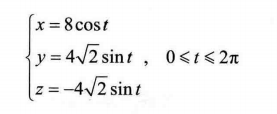

t = 0:pi/50:2*pi;
x = 8*cos(t);
y = 4*sqrt(2)*sin(t);
z = -4*sqrt(2)*sin(t);
plot3(x,y,z)
title('plot3 函数使用举例');
xlabel('X');ylabel('Y');zlabel('Z');grid

**2.2 三维曲面**

% 1 生成平面网格坐标矩阵
% 利用 meshgrid 函数生成
x = 0:0.05:10;% 201
y = 0:0.05:10;% 201
[X,Y] = meshgrid(x,y)

% 2 绘制三维曲面函数
% mesh函数，绘制三维网格图   surf函数绘制三维曲面图
% mesh(x,y,z)   surf(x,y,z)
% z矩阵便是网格点上的高度矩阵，x,y是网格坐标矩阵

% example：绘制z = sin(y)*cos(x)
% 1
subplot(2,3,1)
x = 0:0.1:2*pi;
[x,y] = meshgrid(x);
z = sin(y).*cos(x);
mesh(x,y,z);
xlabel('X');ylabel('Y');zlabel('Z');grid;title('mesh函数绘制');grid;

% 2 
subplot(2,3,2)
x = 0:0.1:2*pi;
[x,y] = meshgrid(x);
z = sin(y).*cos(x);
surf(x,y,z);
xlabel('X');ylabel('Y');zlabel('Z');grid;title('surf函数绘制');grid;

% 3
subplot(2,3,3)
x = 0:0.1:2*pi;
[x,y] = meshgrid(x);
z = sin(y).*cos(x);
plot3(x,y,z);
xlabel('X');ylabel('Y');zlabel('Z');grid;title('plot3函数绘制');grid;

% 4
subplot(2,3,4)
x = 0:0.1:2*pi;
[x,y] = meshgrid(x);
z = sin(y).*cos(x);
meshc(x,y,z);
xlabel('X');ylabel('Y');zlabel('Z');grid;title('带等高线的meshc函数绘制');grid;

% 5
subplot(2,3,5)
x = 0:0.1:2*pi;
[x,y] = meshgrid(x);
z = sin(y).*cos(x);
meshz(x,y,z);
xlabel('X');ylabel('Y');zlabel('Z');grid;title('带底座的meshz函数绘制');grid;

% 6
subplot(2,3,6)
x = 0:0.1:2*pi;
[x,y] = meshgrid(x);
z = sin(y).*cos(x);
surfl(x,y,z);
xlabel('X');ylabel('Y');zlabel('Z');grid;title('带有光照效果的的surfl函数绘制');grid;

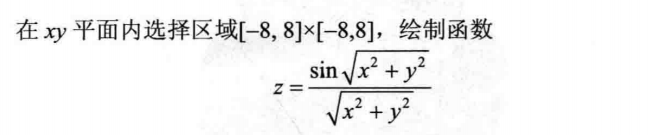

% example:
[x,y] = meshgrid(-8:0.5:8);
z = sin(sqrt(x.^2+y.^2))./sqrt(x.^2+y.^2+eps); %+eps是为了保证分母不为0
subplot(2,2,1);
meshc(x,y,z);
title('由meshc函数绘制');grid;
subplot(2,2,2);
meshz(x,y,z);
title('由meshz函数绘制');grid;
subplot(2,2,3);
surfc(x,y,z);
title('由surfc函数绘制');grid;
subplot(2,2,4);
surfl(x,y,z);
title('由surfl函数绘制');grid;

% 3 标准三维曲面
% 球面
subplot(2,2,1);
[x,y,z] = sphere(30); % 参数决定球面光滑程度，球体半径为1
surf(x,y,z);
title('sphere');

%柱面
subplot(2,2,2);
[x1,y1,z1] = cylinder(3);% 1参数为一个向量，存放柱面各个等间隔高度上的半径，n表是间隔点数量，默认为20
surf(x1,y1,z1);title('cylinder1');

subplot(2,2,3);
[x1,y1,z1] = cylinder(2+sin(0:pi/10:2*pi),30);
surf(x1,y1,z1);title('cylinder2');

% 多峰面
subplot(2,2,4);
[x2,y2,z2] = peaks(40);
surf(x2,y2,z2);title('peaks');


# **3. 隐函数绘图**

    用于未给定函数的显示表达式情况下的绘图操作。主要使用函数 **ezplot( f )。**

**3.1 隐函数二维绘图 ezplot( f )**

% example：f可以是函数文件名或者函数表达式组成的字符串，也可以是匿名函数表达式或函数名
subplot(2,2,1);
ezplot('x^2+y^2-9');grid; 
subplot(2,2,2);
ezplot(@(x,y) x^3+y^3-5*x*y+1/5);grid;
subplot(2,2,3);
ezplot('cos(tan(pi*x))',[0,1]);grid;
subplot(2,2,4);
ezplot('8*cos(t)','4*sqrt(2)*sin(t)',[0,2*pi]);grid;

**3.2 隐函数三维绘图**

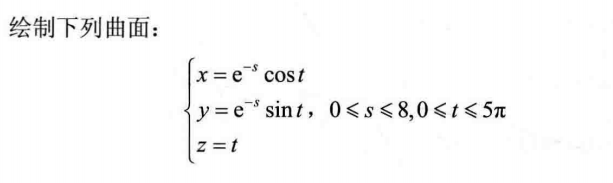

% example: 
ezsurf('exp(-s)*cos(t)','exp(-s)*sin(t)','t',[0,8,0,5*pi])

# **4. 图形修饰**

**4.1 视点处理**

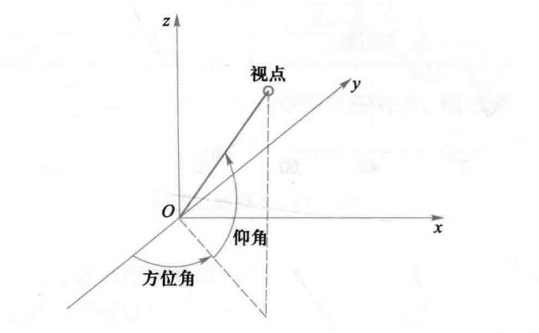

% 从不同的视点观察物体  view(az,el)   az为方位角，el为仰角，默认az=-37.5，el=30
% example:
subplot(2,2,1);mesh(peaks);
view(-37.5,30);
title('视点1');
subplot(2,2,2);mesh(peaks);
view(0,90);
title('视点2');
subplot(2,2,3);mesh(peaks);
view(90,0);
title('视点3');
subplot(2,2,4);mesh(peaks);
view(-7,-10);
title('视点4');

**4.2 色彩处理**

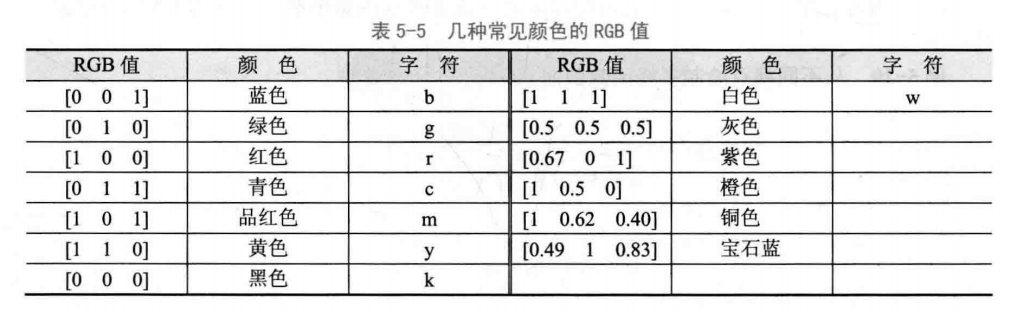

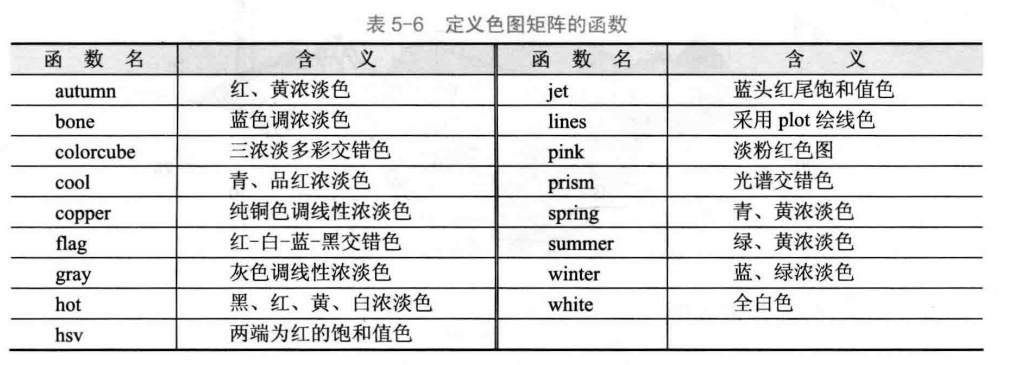

% 颜色的向量表示  元素在[0,1]之间取值，3个元素分别表示RGB的颜色分量。
% 色图着色 colormap
t = 0:pi/20:2*pi;z = peaks(30);
% 使用色图着色
figure(1);colormap("summer");surf(z);shading interp; title('summer');fg1 = getframe(gcf);
figure(2);colormap("cool");surf(z);shading interp; title('cool');fg2 = getframe(gcf);
figure(3);colormap("pink");surf(z);shading interp; title('pink');fg3 = getframe(gcf);
figure(4);colormap("hot");surf(z);shading interp; title('hot');fg4 = getframe(gcf);
figure(5);colormap("spring");surf(z);shading interp; title('spring');fg5 = getframe(gcf);
figure(6);colormap("copper");surf(z);shading interp; title('copper');fg6 = getframe(gcf);

close all;
figure(7);
subplot(231);imshow(fg1.cdata);
subplot(232);imshow(fg2.cdata);
subplot(233);imshow(fg3.cdata);
subplot(234);imshow(fg4.cdata);
subplot(235);imshow(fg5.cdata);
subplot(236);imshow(fg6.cdata);


**4.3 利用色图以及shading进行三维曲面着色演示**

% example:
t = 0:pi/20:2*pi;
z = peaks(20);
% 使用色图着色
colormap("summer");

subplot(2,2,1);surf(z);
% shading改变着色方式
subplot(2,2,2);surf(z);shading flat; %平滑着色，相对光滑
subplot(2,2,3);surf(z);shading interp; % 插值着色，最光滑
subplot(2,2,4);mesh(z);shading interp;

**4.4 图形的裁剪处理**

% 利用NaN常数剔除设置不可使用的数据
% example:裁剪正弦函数大于0.5部分的幅值
x = 0:pi/10:4*pi;
y = sin(x);
plot(x,y,'--k');
hold on;
i = find(y>0.5);
x(i) = NaN;
plot(x,y,'r');

# **5. Matlab中对图像的基本操作**

**    - 图像读入/读出等**

% imread 
% img1 = imread(filename,fmt)
img1 = imread('111.jpg');
image(img1);
[imgData,map] = imread('111.jpg');

 clear;clc